data =readtable('Log.csv');


[a1WaitTimes,a1mean]=meanWaitingTime(data,0);
[bWaitTimes,bmean]=meanWaitingTime(data,1);
[a2WaitTimes,a2mean]=meanWaitingTime(data,2);


[a1Upper,a1Lower]=confidenceInterval(a1WaitTimes)

n = 75

mu = 0.1124

a1Upper = 0.1213

a1Lower = 0.1035

[bUpper,bLower]=confidenceInterval(bWaitTimes)

n = 72

mu = 0.1096

bUpper = 0.1211

bLower = 0.0980

[a2Upper,a2Lower]=confidenceInterval(a2WaitTimes)

n = 68

mu = 0.1079

a2Upper = 0.1173

a2Lower = 0.0985

creation=data(strcmp(data{:,1}, 'Creation') & (data{:,5}==0), 2);
arrive=data(strcmp(data{:,1}, 'Ambulance at Patient') & (data{:,5}==0), 2);

timeBeforePickup=arrive{:,1}-creation{:,1};
a1WaitedMoreThanFifteen=timeBeforePickup(timeBeforePickup>0.25);
[a1moreThanFifteenUpper, a1moreThanFifteenLower]=confidenceInterval(a1WaitedMoreThanFifteen)

n = 1

mu = 0.2648

a1moreThanFifteenUpper = NaN

a1moreThanFifteenLower = NaN

percentageofA1waitedMoreThanFifteen=length(a1WaitedMoreThanFifteen)/size(creation,1)

percentageofA1waitedMoreThanFifteen = 0.0133


[a1waitUpper,a1waitLower]=confidenceInterval(timeBeforePickup)

n = 75

mu = 0.0628

a1waitUpper = 0.0708

a1waitLower = 0.0548

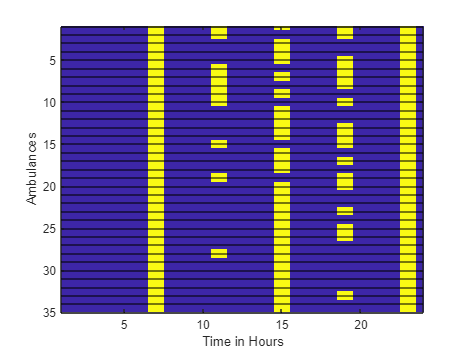

shiftchanges=data(strcmp(data{:,1},'Crew Change'),[2,4]);
makeFig(shiftchanges,24)

function [waitTime,res]=meanWaitingTime(d,t)
    creation=d(strcmp(d{:,1}, 'Creation') & (d{:,5}==t), 2);
    arrive=d(strcmp(d{:,1}, 'Ambulance at Patient') & (d{:,5}==t), 2);
    process=d(strcmp(d{:,1}, 'Patient Processed') & (d{:,5}==t), 2);
    
    delay=arrive{:,1}-creation{:,1};
    serviceTime=process{:,1}-arrive{:,1};
    waitTime=delay+serviceTime;
    res=sum(waitTime)/length(waitTime);
end

function []=makeFig(sc,maxTime)
    labels=(sc{:,2});
    
    for i=1:length(labels)
        v=strsplit(labels{i} ," ");
        sc(i,2)=v(2);
        sc(i,1)=table(round(sc{i,1}));
    end

    sched=zeros(35,maxTime);
    for i=1:size(sc,1)
        sched(cellfun(@str2num,sc{i,2}),sc{i,1})=100;
    end

    figure
    image(sched,'CDataMapping','scaled')
    ylabel('Ambulances')
    xlabel("Time in Hours")
    
    for i=1:35
        yline(i,"Color","black")
    end
%{
    for i=1:maxTime
            xline(i,"Color","black")
    end
%}
    
    axis([1 maxTime 1 35])


end


function [upper,lower]= confidenceInterval(d)
    
    n=length(d)
    mu=sum(d)/n
    s= (sum((d-mu).^2)/(n-1))^(.5);
    upper=mu+(1.96)*(s/(n)^(.5));
    lower=mu-(1.96)*(s/(n)^(.5));
end